# **Práctica 1: Análisis de la Respuesta Temporal de un Sistema de Control Digital**

Las practicas de la asignatura Control con Computador consisten en el estudio de un servomecanismo de posicionamiento angular (LJ Technical Systems) controlado por un PC. Las sesiones de laboratorio P1 y P2 se centran en el análisis experimental de las respuestas temporal y frecuencial del sistema respectivamente. La sesión P3 se dedica al diseño de controladores PID.

**OBJETIVO: Análisis de la respuesta temporal de un sistema de control digital para diferentes periodos de muestreo. Análisis de la precisión y de la estabilidad.**

**En esta sesión el estudiante ha de:**

- **Familiarizarse con el sistema: con la planta de tiempo continuo y con el uso del computador como generador de señales, osciloscopio y controlador digital.**

- **Evaluar las prestaciones (precisión y estabilidad) del sistema en función del periodo de muestreo.**

# Ejercicio 1: Respuesta del sistema en lazo abierto para la señal del tacómetro.

Abrir y ejecutar el modelo P1_Ex1.slx. Comprobar que es la respuesta típica de un sistema de primer orden y cómo varía la ganancia estática si aplicamos al motor el freno magnético. Identificar la constante de tiempo $\tau_0$ y la ganancia estática $K_0$ para una entrada escalón de 1V. 

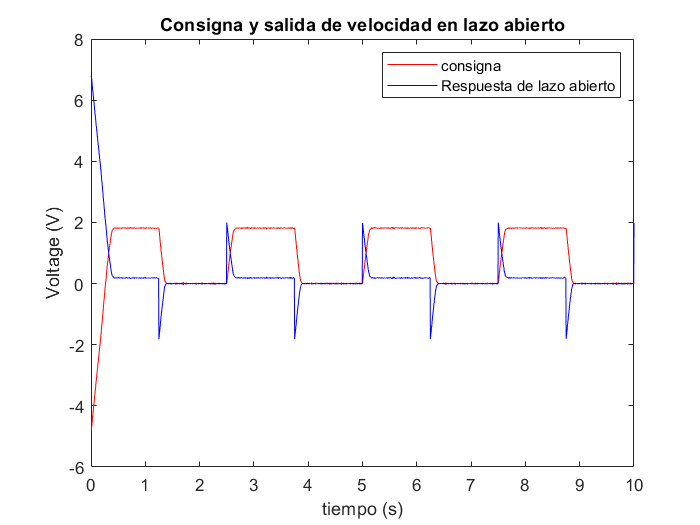

% Inicialización de variables
Tg=0.005; % Tiempo de graficación [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

open P1_Ex1.slx
run P1_Ex1.slx

% Dibujar la respuesta del motor
figure
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,1,:)],'r')
hold on
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,2,:)],'b')
xlabel('tiempo (s)');
ylabel('Voltage (V)');
title('Consigna y salida de velocidad en lazo abierto');
legend('Consigna','Respuesta de lazo abierto');

# Ejercicio 2: Respuesta del sistema en lazo cerrado con realimentación de velocidad.

Abrir y ejecutar el modelo P1_Ex2.slx. Comprobar cómo varía el error en estado estacionario para Kp= 1, 2, 5 y 10, cambiando el bloque "Controlador Proporcional"

% Inicialización de variables
Tg=0.005; % Tiempo de graficación [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

open P1_Ex2.slx

figure
plot(Kp01.time,[Kp01.signals.values(:,1,:)],'r') 
hold all
plot(Kp1.time, [Kp01.signals.values(:,3,:)],'g')
plot(Kp2.time, [Kp05.signals.values(:,3,:)],'b')
plot(Kp5.time, [Kp5.signals.values(:,3,:)],'k')
plot(Kp10.time, [Kp10.signals.values(:,3,:)],'m')

xlabel('tiempo (s)');
ylabel('Voltage (V)');
title('Consigna y salida de velocidad en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Kp=1','Kp=2','Kp=5','Kp=10');

# Ejercicio 3: Evaluación experimental de las prestaciones del sistema en lazo cerrado con realimentación de velocidad. 

Abirir y ejecutar el modelo P1_Ex3.slx. Evaluar cómo varía la precisión y la estabilidad del sistema para diferentes periodos de muestreo.

% Inicialización de variables
Tg= 0.005; % Tiempo de graficación [seg]
Ts=0.01; % Tiempo de muestreo
Vmax=5; % [V]
Vmin=-5; % [V]

open P1_Ex3.slx

% salida
figure(1)
plot(Ts5ms.time,[Ts5ms.signals.values(:,2,:)],'r')
hold all
plot(Ts5ms.time, [Ts5ms.signals.values(:,3,:)],'g')
plot(Ts10ms.time, [Ts10ms.signals.values(:,3,:)],'b')
plot(Ts50ms.time, [Ts50ms.signals.values(:,3,:)],'k')
plot(Ts02s.time, [Ts02s.signals.values(:,3,:)],'m')
plot(Ts05s.time, [Ts05s.signals.values(:,3,:)],'c')
xlabel('tiempo (s)');
ylabel('Voltage (V)');
title('Consigna y salida de velocidad en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.2s','Ts=0.5s')

% error
figure(2)
plot(Ts5ms.time,[Ts5ms.signals.values(:,2,:)],'r')
hold all
plot(Ts5ms.time, [Ts5ms.signals.values(:,1,:)],'g')
plot(Ts10ms.time, [Ts10ms.signals.values(:,1,:)],'b')
plot(Ts50ms.time, [Ts50ms.signals.values(:,1,:)],'k')
plot(Ts02s.time, [Ts02s.signals.values(:,1,:)],'m')
plot(Ts05s.time, [Ts05s.signals.values(:,1,:)],'c')
xlabel('tiempo (s)');
ylabel('Voltage (V)');
title('Consigna y señal de mando de velocidad en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.2s','Ts=0.5s')

# Ejercicio 4: Respuesta del sistema en lazo abierto para la señal del potenciómetro.

Abrir y ejecutar el modelo P1_Ex4.slx. Comprobar que es la respuesta típica de un sistema de tipo 1. 

% Inicialización de variables
Tg=0.005; % Tiempo de graficación [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

open P1_Ex4.slx
run P1_Ex4.slx

% Dibujar la respuesta del motor
figure
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,1,:)],'r')
hold on
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,2,:)],'b')
xlabel('tiempo (s)');
ylabel('Voltage (V)');
title('Consigna y salida de posición en lazo abierto');
legend('Consigna','Respuesta de lazo abierto');

# Ejercicio 5: Respuesta del sistema en lazo cerrado con realimentación de posición.

Abrir y ejecutar el modelo P1_Ex5.slx. Comprobar cómo varía el error en estado estacionario para Kp= 1, 2 y 3, cambiando el bloque "Controlador Proporcional".

% Inicialización de variables
Tg=0.005; % Tiempo de graficación [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

open P1_Ex5.slx

figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all
plot(Kp1.time, [Kp1.signals.values(:,1,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,1,:)],'b')
plot(Kp3.time, [Kp3.signals.values(:,1,:)],'k')

xlabel('tiempo (s)');
ylabel('Voltage (V)');
title('Consigna y salida de posición en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Kp=1','Kp=2','Kp=3');

# Ejercicio 6: Evaluación experimental de las prestaciones del sistema en lazo cerrado con realimentación de posición. 

Abirir y ejecutar el modelo P1_Ex6.slx. Evaluar cómo varía la precisión y la estabilidad del sistema para diferentes periodos de muestreo.

% Inicialización de variables
Tg= 0.005; % Tiempo de graficación [seg]
Ts=0.01; % Tiempo de muestreo
Vmax=5; % [V]
Vmin=-5; % [V]

open P1_Ex6.slx

% salida
figure(1)
plot(Ts5ms.time,[Ts5ms.signals.values(:,2,:)],'r')
hold all
plot(Ts5ms.time, [Ts5ms.signals.values(:,3,:)],'g')
plot(Ts10ms.time, [Ts10ms.signals.values(:,3,:)],'b')
plot(Ts50ms.time, [Ts50ms.signals.values(:,3,:)],'k')
xlabel('tiempo (s)');
ylabel('Voltage (V)');
title('Consigna y salida de posición en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s')

% error
figure(2)
plot(Ts5ms.time,[Ts5ms.signals.values(:,2,:)],'r')
hold all
plot(Ts5ms.time, [Ts5ms.signals.values(:,1,:)],'g')
plot(Ts10ms.time, [Ts10ms.signals.values(:,1,:)],'b')
plot(Ts50ms.time, [Ts50ms.signals.values(:,1,:)],'k')
xlabel('tiempo (s)');
ylabel('Voltage (V)');
title('Consigna y señal de mando de posición en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s')